Setuo

A = load('MatlabGiven/mat1.txt');
sol = sort(eig(A), 'descend');

QR iteratie zonder shifts

[E1, res_zonder] = qr_zondershift(A);

res_zonder =     7.8074    5.1272    3.2446    2.2259    1.6600    1.3065    1.0643    0.8919    0.7683    0.6800    0.6170    0.5714    0.5376    0.5115    0.4902    0.4720    0.4558    0.4409    0.4267    0.4131    0.3998    0.3869    0.3741    0.3616    0.3493    0.3372    0.3254    0.3137    0.3023    0.2912    0.2804    0.2698    0.2595    0.2495    0.2398    0.2303    0.2212    0.2124    0.2038    0.1956    0.1876    0.1799    0.1725    0.1654    0.1585    0.1519    0.1456    0.1395    0.1336    0.1280
    6.0215    4.9213    4.3456    3.7643    3.0745    2.6558    2.5243    2.5109    2.4737    2.3517    2.1462    1.8903    1.6218    1.3687    1.1459    0.9581    0.8041    0.6799    0.5806    0.5016    0.4385    0.3879    0.3469    0.3133    0.2853    0.2617    0.2415    0.2239    0.2085    0.1947    0.1824    0.1712    0.1610    0.1517    0.1431    0.1352    0.1278    0.1209    0.1145    0.1086    0.1029    0.0977    0.0927    0.0881    0.0837    0.0796    0.0757    0.0720    0.

norm_res_zonder = zeros(size(res_zonder, 2), 1);
for i = 1:size(res_zonder,2)
    norm_res_zonder(i) = norm(res_zonder(:, i));
end
norm_res_zonder

norm_res_zonder =    26.1465
   25.0916
   23.4574
   22.0728
   20.9219
   19.7402
   18.0620
   17.1553
   15.8974
   14.9992


QR iteratie  met Rayleigh quotient shift

[E2, res_ray] = qr_rayleighshift(A);
norm_res_ray = zeros(size(res_ray, 2), 1);
for i = 1:size(res_ray, 2)
    norm_res_ray(i) = norm(res_ray(:, i));
end
norm_res_ray

norm_res_ray =    26.1465
   25.0718
         0


QR iteratie met Wilkinson shift

[E3, res_wilk] = qr_wilkinsonshift(A);
norm_res_wilk = zeros(size(res_wilk, 2), 1);
for i = 1:size(res_wilk, 2)
    norm_res_wilk(i) = norm(res_wilk(:, i));
end
norm_res_wilk

norm_res_wilk =    26.1465
   25.0716
         0


Plotten

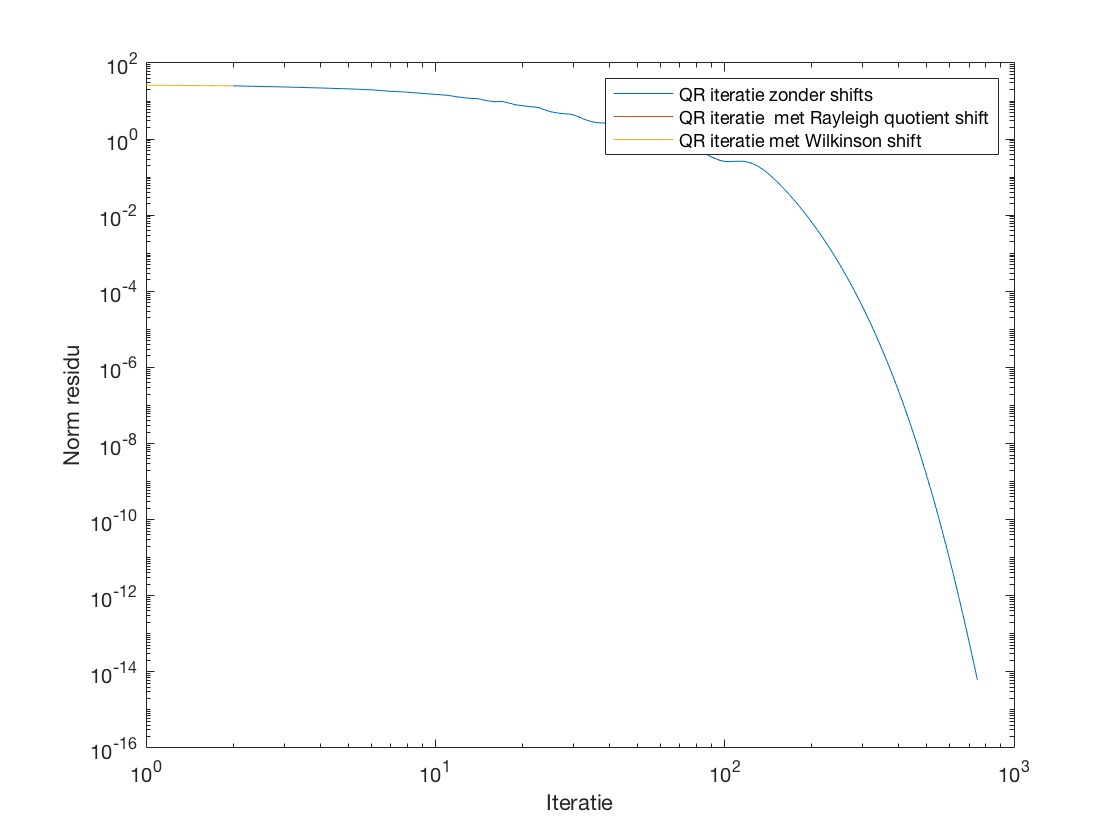

figure
loglog(norm_res_zonder);
hold on;
loglog(norm_res_ray);
loglog(norm_res_wilk);
legend('QR iteratie zonder shifts', 'QR iteratie  met Rayleigh quotient shift', 'QR iteratie met Wilkinson shift');
xlabel('Iteratie');
ylabel('Norm residu');